# **디지털신호처리 ****HW#1**

Due date : 2021.10.21. 23:59

**이름**** :정지원**

**학번**** :201714625**

아래 문제에 대하여 MATLAB으로 구현하고 mlx파일을 본인의 Github에 업로드 하고 링크 주소를 적으세요.

**Repository 링크 : **

1. 다음 신호를 stem 함수를 이용하여 그려라.

1) 

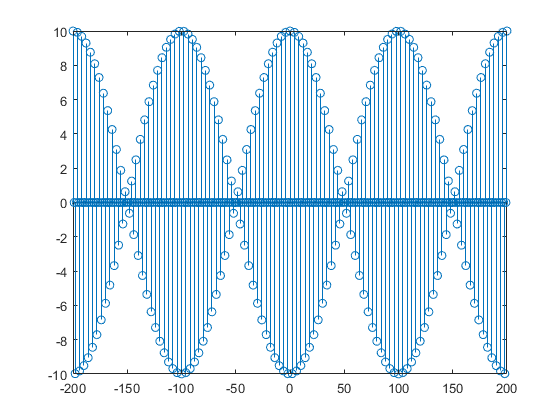

n = [-200:200];
x5 = 5*[cos(0.49*pi*n) + cos(0.51*pi*n)];
stem(n,x5)

2) 

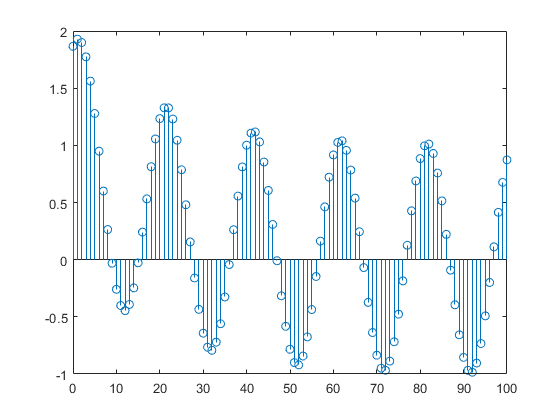

n = [0:100];
x2 = exp(-0.05*n);
x1 = sin(0.1*pi*n+pi/3);
x7 = x2 + x1;
stem(n,x7)

2.  (P2.16) LTI 시스템의 차분 방정식이 다음과 같다.


$$y\left(n\right)-0\ldotp 5y\left(n-1\right)+0\ldotp 25y\left(n-2\right)=x\left(n\right)+2x\left(n-1\right)+x\left(n-3\right)$$


1) MATLAB의 impz 함수를 사용하여 0<=n<=100 구간에서 시스템의 임펄스 응답을 구하고 stem을 이용해서 그려라.

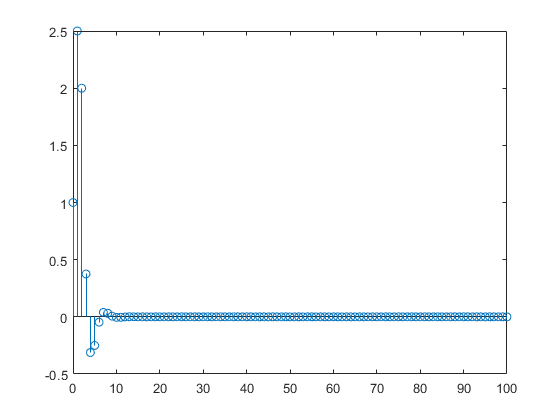

n = [0:100];
a = [1, -0.5, 0.25]; b = [1, 2, 1];
h = impz(b,a,n);
stem(n,h);

2) 이 임펄스 응답으로부터 안정성을 판별하라. (sum, abs 함수 사용)

sum(abs(h))

ans = 6.5714

3) 만약 이 시스템의 입력이 x(n) = [5+3cos(0.2pi*n)+4sin(0.6pi*n)]*u(n) 이면, filter 함수를 사용하여0<=n<=200 구간에서 응답 y(n)을 구하라.

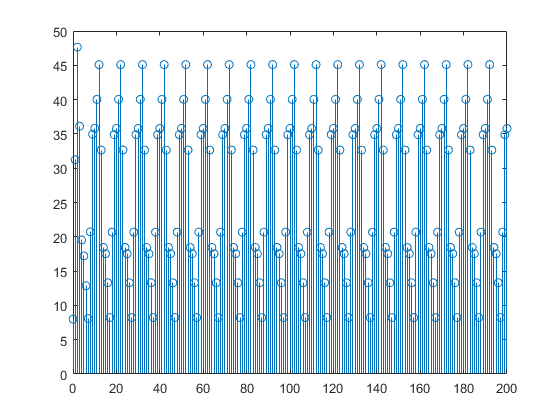

n = [0:200];
x =  [5+3*cos(0.2*pi*n) + 4*sin(0.6*pi*n)];
s = filter(b,a,x);
stem(n,s);

3. (P2.20) 

일 때, 다음을 그려라. 

1) y(n)의 처음 51개 샘플을 stem 함수 이용해서 그려라. 

% stem을 사용할 시 x와 y의 길이를 동일시 하는 방법을 잘 모르겠습니다


2) x(n)과 h(n)을 26개의 샘플이 되도록 자른뒤, conv 함수를 이용해서 y(n)을 구하고 stem 이용해서 그려라. 

3) filter 함수를 이용해서 $x\left(n\right)\ast h\left(n\right)$의 처음 51개 샘플을 구하고 stem 이용해서 그려라. 

4. (P3.14) 임펄스 응답으로 기술된 각 선형 시불변 시스템에 대해 구간 $\left\lbrack -\pi ,\pi \right\rbrack$에서 주파수 응답 함수 $H\left(e^{j\omega } \right)$을 구하고 크기 응답과 위상 응답을 그려라. 

1) $h\left(n\right)={\left(0\ldotp 9\right)}^{|n|}$

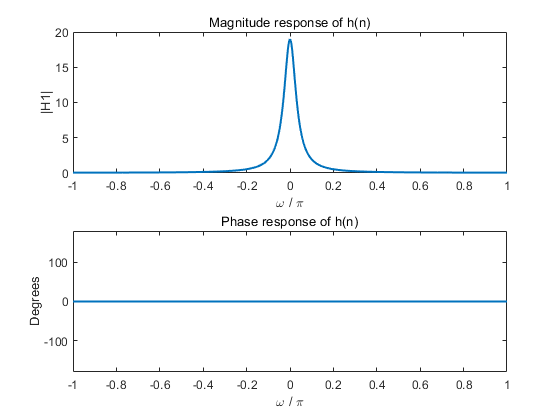

w1 = [-300:300]*pi/300;
H1 = 0.19*ones(size(w1))./(1.81-1.8*cos(w1));
magH1 = abs(H1);
phaH1 = angle(H1)*180/pi;

subplot(2,1,1); plot(w1/pi,magH1,'LineWidth',1.5); axis([-1 1 0 20]);
wtick = [-1:0.2:1]; magtick = [0:5:20];
xlabel('\omega / \pi'); ylabel('|H1|');
title('Magnitude response of h(n)');

subplot(2,1,2); plot(w1/pi,phaH1,'LineWidth',1.5); axis([-1 1 -180 180]);
wtick = [-1:0.2:1]; magtick = [-180:60:180];
xlabel('\omega / \pi'); ylabel('Degrees');
title('Phase response of h(n)');

2) $h\left(n\right)=\left\lbrack {\left(0\ldotp 5\right)}^n +{\left(0\ldotp 4\right)}^n \right\rbrack u\left(n\right)$

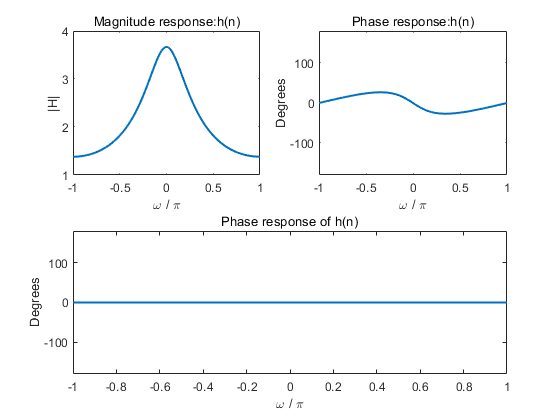

w2 = [-300:300]*pi/300;
H2 = (2-0.9*exp(-j*w2))./(1-0.9*exp(-j*w2)+0.2*exp(-j*2*w2));
magH2 = abs(H2); 
phaH2 = angle(H2)*180/pi; 

subplot(2,2,1); plot(w2/pi,magH2,'LineWidth',1.5); axis([-1 1 1 4]);
wtick = [-1:0.2:1]; magtick = [0:0.5:4];
xlabel('\omega / \pi'); ylabel('|H|');
title('Magnitude response:h(n)');

subplot(2,2,2); plot(w2/pi,phaH2,'LineWidth',1.5); axis([-1 1 -180 180]);
wtick = [-1:0.2:1]; magtick = [-180:60:180];
xlabel('\omega / \pi'); ylabel('Degrees');
title('Phase response:h(n)');

5. (P3.17) 

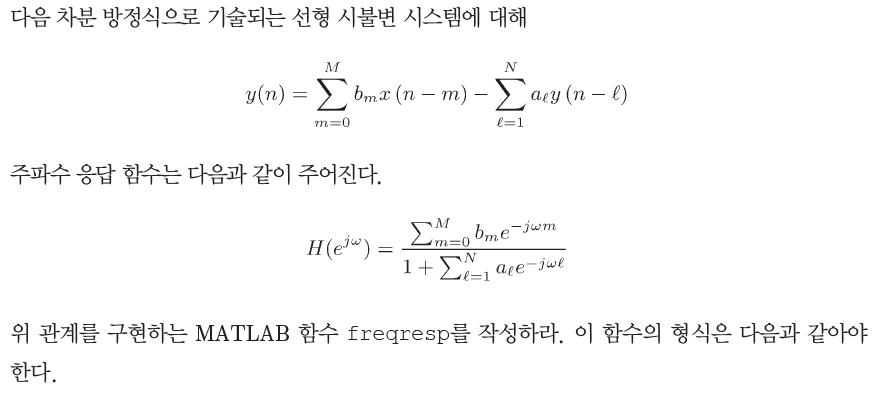

function [H] = freqresp(b,a,w)
% H = frequency response array evaluated at w frequencies
% b = numerator coefficient array
% a = denominator coefficient array (a(1) = 1)
% w = frequency location array
a = reshape(a,1,length(a));
b = reshape(b,1,length(b));
w = reshape(w,1,length(w));

m = 0:length(b)-1; 
num = b*exp(-j*m'*w);

l = 0:length(a)-1; 
den = a*exp(-j*l'*w);
H = num./den;
end


6. (P3.19) 다음의 각 시스템에 대해 $H\left(e^{j\omega } \right)$을 구하고, 그 크기와 위상을 그려라

1) $y\left(n\right)=x\left(n\right)-x\left(n-2\right)+0\ldotp 95y\left(n-1\right)-0\ldotp 9025y\left(n-2\right)$

% freqresp 오류가 생김니다
% 스크립트의 함수 정의는 파일의 끝에 표기되어야 합니다.
% freqresp 함수 정의 뒤에 있는 모든 명령문을 첫 번째 로컬 함수 정의 앞으로 이동하십시오.

2) $y\left(n\right)=x\left(n\right)-\sum_{l=1}^5 {\left(0\ldotp 5\right)}^n y\left(n-l\right)$